1.Importing Dataset

% Datasetin bulunduğu ana klasör yolu
datasetPath = fullfile('C:\Users\necka\OneDrive\Masaüstü\24-25 Bahar\ANN\Final Project', 'architectural-styles-dataset');

% Görselleri alt klasörlere göre otomatik etiketleyecek şekilde içeri aktar
imds = imageDatastore(datasetPath, ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Veri kümesinin genel durumu
disp('Toplam görüntü sayısı:');

Toplam görüntü sayısı:


disp(numel(imds.Files));

       10111




disp('Sınıflar:');

Sınıflar:


disp(categories(imds.Labels));

    {'Achaemenid architecture'         }
    {'American Foursquare architecture'}
    {'American craftsman style'        }
    {'Ancient Egyptian architecture'   }
    {'Art Deco architecture'           }
    {'Art Nouveau architecture'        }
    {'Baroque architecture'            }
    {'Bauhaus architecture'            }
    {'Beaux-Arts architecture'         }
    {'Byzantine architecture'          }
    {'Chicago school architecture'     }
    {'Colonial architecture'           }
    {'Deconstructivism'                }
    {'Edwardian architecture'          }
    {'Georgian architecture'           }
    {'Gothic architecture'             }
    {'Greek Revival architecture'      }
    {'International style'             }
    {'Novelty architecture'            }
    {'Palladian architecture'          }
    {'Postmodern architecture'         }
    {'Queen Anne architecture'         }
    {'Romanesque architecture'         }
    {'Russian Revival architecture'    }
    {'Tudor Revi

2. Dividing dataset into %80,%10,%10 for train,test and validation

% Rastgele ama tekrarlanabilir bir şekilde bölmek için random seed ayarlanır
rng(1);

% Her bir sınıf için görüntüleri ayrı ayrı böl
[imdsTrain, imdsRest] = splitEachLabel(imds, 0.8, 'randomized');  % %80 Train
[imdsValidation, imdsTest] = splitEachLabel(imdsRest, 0.5, 'randomized'); % %10 Validation, %10 Test

% Kontrol amaçlı boyutları göster
disp("Eğitim verisi sayısı:");

Eğitim verisi sayısı:


disp(numel(imdsTrain.Files));

        8090




disp("Doğrulama verisi sayısı:");

Doğrulama verisi sayısı:


disp(numel(imdsValidation.Files));

        1017




disp("Test verisi sayısı:");

Test verisi sayısı:


disp(numel(imdsTest.Files));

        1004




% Giriş boyutu (genellikle 224x224x3)
inputSize = net.Layers(1).InputSize;

% Görselleri modele uygun boyuta getirmek için imds'leri yeniden tanımla
augimdsTrain = augmentedImageDatastore(inputSize(1:2), imdsTrain, ...
    'ColorPreprocessing', 'gray2rgb');

augimdsValidation = augmentedImageDatastore(inputSize(1:2), imdsValidation, ...
    'ColorPreprocessing', 'gray2rgb');

augimdsTest = augmentedImageDatastore(inputSize(1:2), imdsTest, ...
    'ColorPreprocessing', 'gray2rgb');
info = readimage(imdsTrain, 1);
disp(size(info));  % [yükseklik genişlik kanal_sayısı]

         442        1000           3



3. Training Options

% Eğitim seçeneklerini belirle
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 32, ...
    'MaxEpochs', 6, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

4. Training the Model

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |        3.12% |        4.92% |       4.0533 |       3.6137 |      1.0000e-04 |
|       1 |          30 |       00:00:50 |        0.00% |        7.37% |       3.4186 |       3.4268 |      1.0000e-04 |
|       1 |          50 |       00:01:10 |        3.12% |              |       3.2957 |              |      1.0000e-04 |
|       1 |          60 |       00:01:26 |        6.25% |        8.95% |       3.2835 |   

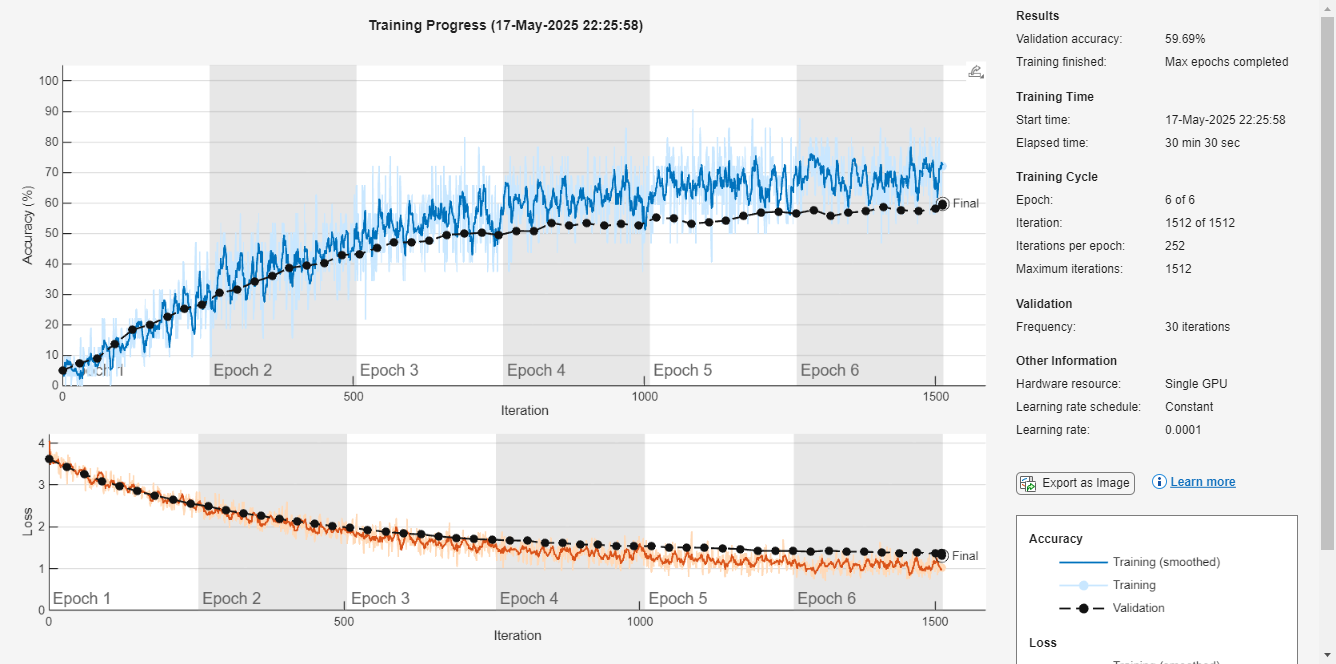

% ResNet-50 modelini yükle
net = resnet50;

% Ağın son katmanlarını hedef sınıflara göre değiştir
lgraph = layerGraph(net);

% ResNet-50'nin son 3 katmanını çıkar
lgraph = removeLayers(lgraph, {'fc1000','fc1000_softmax','ClassificationLayer_fc1000'});

% Yeni sınıf sayısını belirle
numClasses = numel(categories(imdsTrain.Labels));

% Yeni katmanlar
newLayers = [
    fullyConnectedLayer(numClasses, 'Name', 'fc_new')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classoutput')];

% Yeni katmanları grafiğe ekle
lgraph = addLayers(lgraph, newLayers);

% Eski son katmanın çıktısını yeni fullyConnected katmanına bağla
lgraph = connectLayers(lgraph, 'avg_pool', 'fc_new');

% Ağı eğit
trainedNet = trainNetwork(augimdsTrain, lgraph, options);

5. Modeli Kaydetme

% Eğitilmiş modeli kaydet
modelName = 'resnet50_architecture_model.mat';
save(modelName, 'trainedNet');
fprintf('Model "%s" olarak kaydedildi.\n', modelName);

Model "resnet50_architecture_model.mat" olarak kaydedildi.


6. Test Etme

% Test veri kümesinde tahmin yap
[predictedLabels, scores] = classify(trainedNet, augimdsTest);

% Gerçek etiketler
trueLabels = imdsTest.Labels;

% Doğruluk hesabı
accuracy = mean(predictedLabels == trueLabels);
fprintf('Test doğruluğu: %.2f%%\n', accuracy * 100);

Test doğruluğu: 59.56%


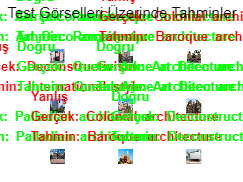


% Test setinden rastgele 9 görüntü seç
numImages = 9;
perm = randperm(numel(imdsTest.Files), numImages);

figure;
for i = 1:numImages
    % Orijinal resmi oku ve yeniden boyutlandır
    img = readimage(imdsTest, perm(i));
    imgResized = imresize(img, inputSize(1:2));
    
    % Gri ise RGB'ye çevir
    if size(imgResized,3) == 1
        imgResized = repmat(imgResized, 1, 1, 3);
    end

    % Tahmin et
    [label, score] = classify(trainedNet, imgResized);

    % Gerçek etiket
    trueLabel = imdsTest.Labels(perm(i));

    % Görseli çiz
    subplot(3,3,i);
    imshow(imgResized);
    
    % Başlık oluştur
    if label == trueLabel
        titleStr = sprintf('\\color{green}Doğru\\newlineGerçek: %s\\newlineTahmin: %s', ...
            string(trueLabel), string(label));
    else
        titleStr = sprintf('\\color{red}Yanlış\\newlineGerçek: %s\\newlineTahmin: %s', ...
            string(trueLabel), string(label));
    end
    title(titleStr, 'FontSize', 10);
end
sgtitle('Test Görselleri Üzerinde Tahminler');

7. Confusion Matrix

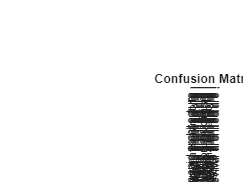

% Test seti üzerinde tahmin yap
[predictedLabels, ~] = classify(trainedNet, augimdsTest);

% Gerçek etiketler
trueLabels = imdsTest.Labels;

% Confusion matrix plot
figure;
confusionchart(trueLabels, predictedLabels, ...
    'Title', 'Confusion Matrix', ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');


% Ek olarak accuracy değeri de verelim
accuracy = mean(predictedLabels == trueLabels);
fprintf('Test doğruluğu: %.2f%%\n', accuracy * 100);

Test doğruluğu: 59.56%
